# **Model Predictive Control for a DC motor**

This live script explores the theory and practice of Model Predictive Control (MPC) with MATLAB's Model Predictive Control Toolbox. It is intended to explain the fundamentals of MPC, a forward-thinking control method noted for its predicted accuracy and adaptability. The script, which focuses on dynamic modelling of DC motors, provides a viable framework for using MPC in real-world applications. The script also contains a hands-on demonstration utilising a real-time DC motor configuration to demonstrate MPC's experimental response.

### 2. What is MPC?

Model Predictive Control (MPC) is a control strategy used by engineers to manage complicated systems. It employs mathematical models to predict future outcomes and adjusts the system's behaviour appropriately, striking a balance between attaining desired goals and adhering to predefined limitations or regulations. This makes MPC especially useful for systems where planning ahead of time is critical to achieving peak performance.

Consider Model Predictive Control (MPC) to be a smart navigator when it comes to controlling the location of a DC motor. This controller continuously anticipates the motor's future positions depending on its current speed and direction. It then adjusts the motor's input power to achieve the desired position while maintaining smooth operation and minimising potential problems such as overshooting the goal or reacting improperly.

### 2. DC Motor Dynamics:

A prior live script provided a detailed explanation on deriving the dynamics of a DC motor [DC-Lab](https://www.mathworks.com/matlabcentral/fileexchange/164976-dc-motor-dynamics-modeling-and-position-control) and a parameter estimation was performed.

#### 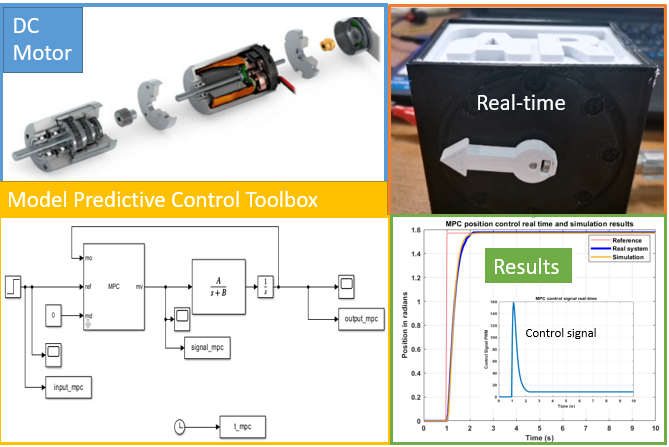

To focus on MPC control in this setting, the motor dynamics is represented by a simplified second order transfer function generated from mechanical dynamics. Voltage (PWM) is the system's input, and position is the output. 

DC motor parameters

$k
$**: Motor constant.**

$v$**: Viscous friction.**

$J
$**: Motor inertia.**

$V$**: Input (voltage).**

 
$$ \frac{\theta(s)}{V(s)}= \frac{\frac{k}{J}}{s(s + \frac{v}{J})}
$$
 
$$= \frac{A}{s(s + B)}$$


### 3. MPC for Position Control

Initially, the procedure begins by importing the A and B values of the DC motor. Following this step, the transfer function is utilized to configure and fine-tune the controller using the MPC Toolbox. Finally, this tailored controller is integrated into the actual DC motor system.

Loading motor parameters

Ts=0.05;
load('estimated_AB.mat'); % Which is the data with a parameter estimation from previous experiments.

#### MPC simulation

By following the steps outlined in this [video](https://www.youtube.com/watch?v=dLHV25--LzM), you can create an MPC to control the motor's position. 

open_system('sim_cont_est_2022b.slx');

Additionally, the code provided below can be uncommented to import a pre-built model. Once loaded, this model can be used to simulate the response of the controller.

%load('mpc_pos.mat');

Plot the simulated MPC input-output response 

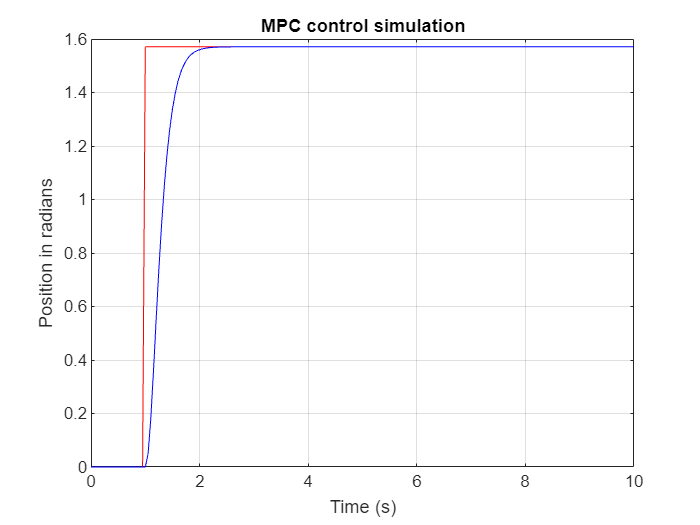

figure(1);
plot(t_mpc,input_mpc,'r',t_mpc,output_mpc,'b');
grid on;
xlabel('Time (s)');
ylabel('Position in radians');
title('MPC control simulation')

#### MPC with a real-time platform (if you have a physical DC motor setup)

Once the controller has been designed, the same controller can then be applied to manage the experimental DC motor system.

% open_system('mpc_position_control_22b.slx');

#### Load the MPC response obtained using the real-time DC motor

In the absence of a physical DC motor setup, the following data can be loaded to facilitate comparative analysis. This data was obtained by means of experiments using the Model Predictive Control toolbox and DC-Lab. The following [video](https://www.youtube.com/watch?v=oEC3d6USJKc) shows the system performance.

load("DC_MPC_REAL_DATA_IN_OUT.mat")

Plot the experimental MPC input-output response 

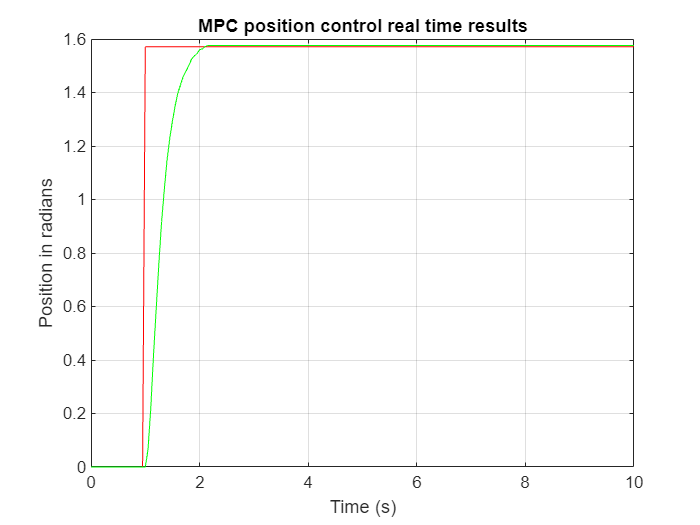

figure(2);plot(t_mpc_real,input_mpc,'r',t_mpc_real,output_mpc_real,'g');grid on;
xlabel('Time (s)');
ylabel('Position in radians');
title('MPC position control real-time results')

### 4.  MPC Real-Time and Simulation Comparison

Input-output response for performance validation 

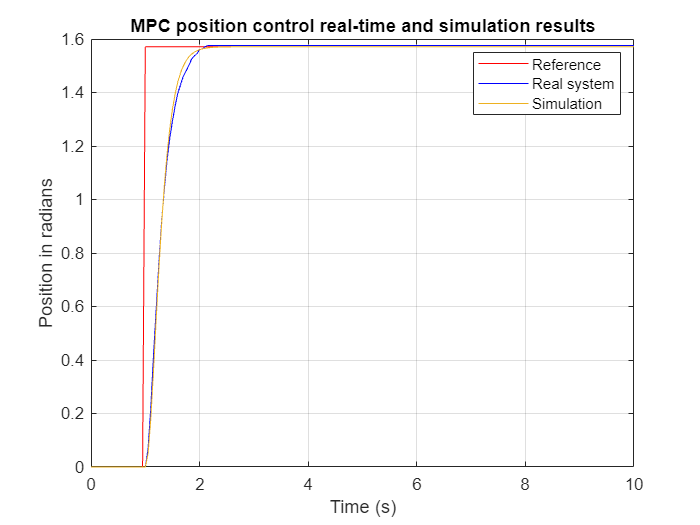

figure(3);plot(t_mpc_real,input_mpc,'r',t_mpc_real,double(output_mpc_real),'b',t_mpc_real,output_mpc);grid on;
legend('Reference', 'Real system', 'Simulation');
xlabel('Time (s)');
ylabel('Position in radians');
title('MPC position control real-time and simulation results')

Control signals 

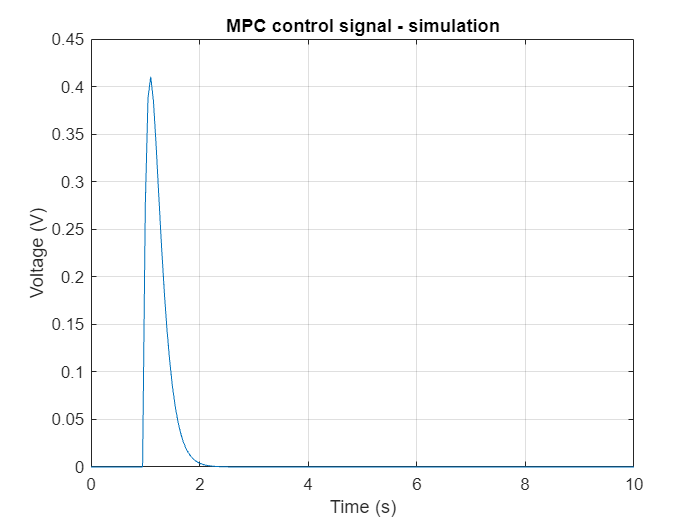

figure(4);plot(t_mpc,signal_mpc);grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('MPC control signal - simulation')

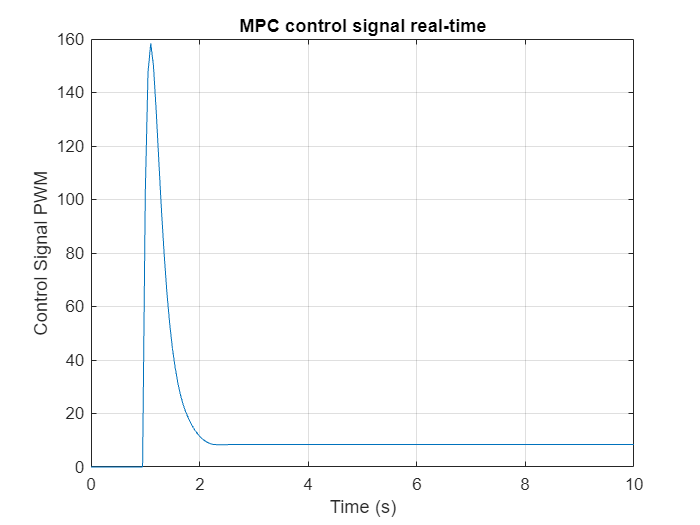

figure(5);plot(t_mpc_real,signal_mpc_real);grid on;
xlabel('Time (s)');
ylabel('Control Signal PWM');
title('MPC control signal real-time')

It is a work by